% Load the pretrained object detection detector and classifier
load("D:\college\FYP\Scripts\Object_Detection\other\ACF\ACF_ODM\ACF_Detector\Stop\ACF_Detector_PreCropped_stop_32.mat");
load("D:\college\FYP\Neural_Networks\5-signs\resnet_18\5-signs\Augmented\10-epochs\Network.mat"); % Load your classifier model


% Ask the user to select an image file
[imageName, imagePath] = uigetfile({'*.jpg;*.png;*.bmp;'},'Select an image file');
fullImagePath = fullfile(imagePath, imageName);

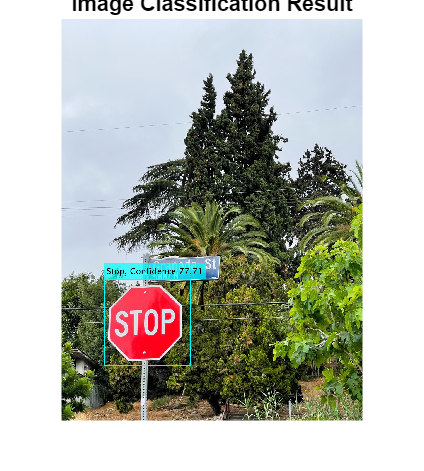


% Check if the user canceled the file selection
if isequal(imageName, 0)
    fprintf('No image file selected.\n');
else
    % Read the selected image
    img = imread(fullImagePath);

    % Detect objects in the image
    [bboxes, scores] = detect(Stop, img, 'Threshold', 1);

    % Check if at least one object is detected in the image
    if ~isempty(bboxes)
        % Select the strongest detection
        [~, idx] = max(scores);
        detectedObject = imcrop(img, bboxes(idx, :)); % Crop the detected object

        % Resize the object image to the required size for classification
        resizedObject = imresize(detectedObject, [224, 224]);

        % Classify the object using the pretrained classifier
        classLabel = classify(Network, resizedObject);

        % Create a custom style for annotation (bold border)
        annotationStyle = struct('Color', 'cyan', 'FontSize', 30, ...
            'TextBoxOpacity', 0.7, 'LineWidth', 3);  % Increase LineWidth to make the border bold

        % Add bounding box with label to the image using custom style
        img_with_bbox = insertObjectAnnotation(img, 'rectangle', bboxes(idx, :), ...
            sprintf('%s, Confidence %4.2f', char(classLabel), scores(idx)), ...
            annotationStyle);

        % Display the image with the bold bounding box and label
        figure;
        imshow(img_with_bbox);
        title('Image Classification Result', 'FontSize', 12);
    else
        fprintf('No object detected in the image.\n');
    end
end